# Principal Components Analysis (PCA)

*Shira Lupkin - 2020*

Pricipal Component Analysis, PCA, is popular linear dimensionality technique in neuroscience. The object of PCA is to define a set of vectors/directions (i.e., principal components) in feature-space that capture the largest amount of variance in the data. We can then project the data onto these vectors for a lower-dimensional representation of the data that preserves the covariance of the original data. 

Within neuroscience PCA is used for a variety of different types of analyses including. For this document, we use PCA to sort spikes* based off of the neurons that generated them. PCA is an example of *unsupervised* dimensionality reduction technique. In other words, the spike sorting is being done in the absence of any *a priori* knowledge about which waveform belongs to which neuron. 

*NB: this is not the only way to perform spike sorting. 

## Explanation of PCA Procedure

The spike sorting example uses PCA to reduce the data from 40-dimensiosn to something more manageable. So, before we go into this, let's start with a simpler (albeit abstract) example in which the dataset has 2 dimensions. Let's call them Variable 1 and Variable 2.  

### Step 1: Center (and Scale) the Data

Since PCA is only concerned with the variance of the data, the first step to pre-processing data for PCA is to center the data by subtracting the mean for each input variable. This removes the influence of the mean of a given variable from biasing the overall results. Note in figure below, that this operation shifts the data to the center but the points are still in the same positions relative to each other. 

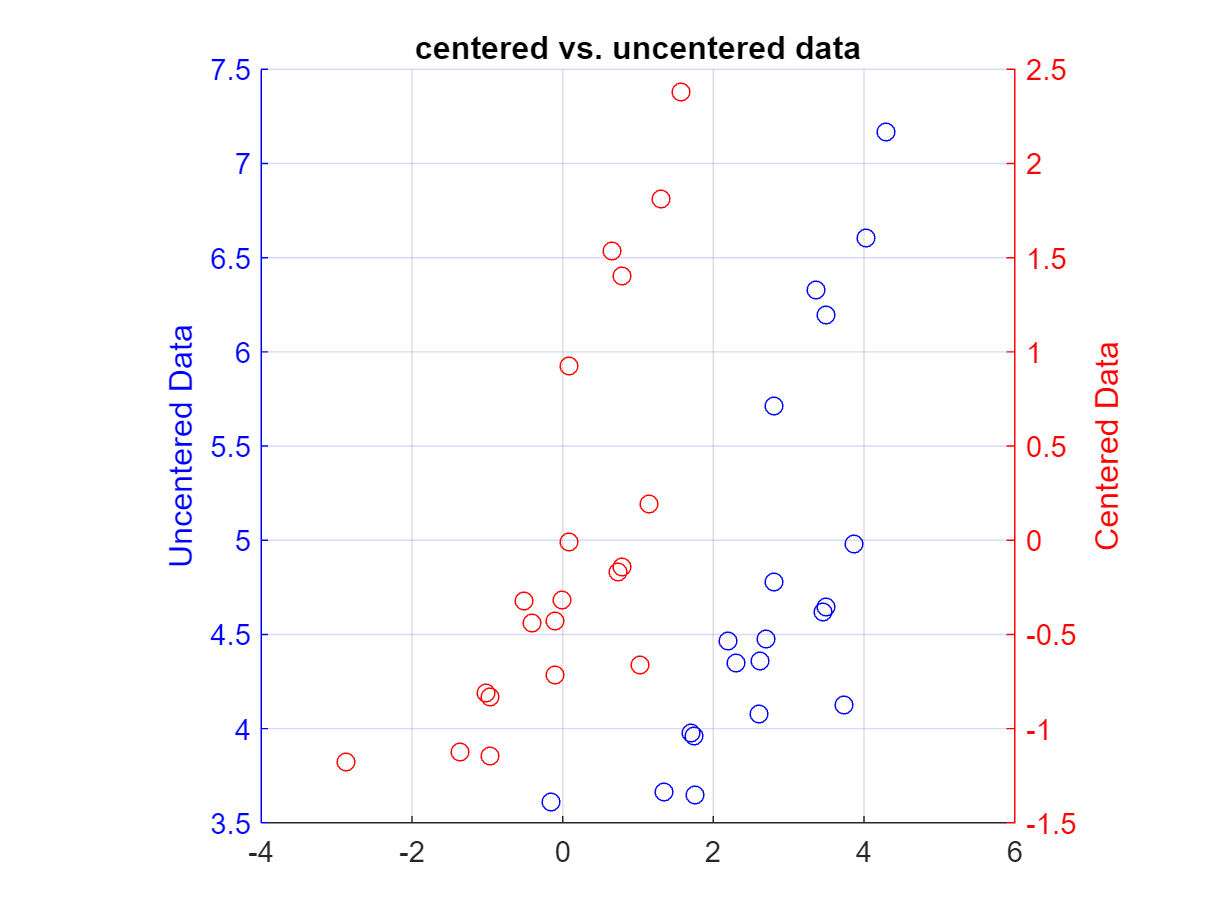

load ../data/toyData
figure(1)
clf
centered1 = x1-mean(x1); 
centered2 = x2-mean(x2); 

% plot the centered and uncentered datasets on the same graph
leftColor = [0 0 1];
rightColor = [1 0 0];
set(gcf,'defaultAxesColorOrder',[leftColor; rightColor]);
yyaxis left
scatter(x1,x2,'bo')
ylabel('Uncentered Data')
yyaxis right
scatter(centered1,centered2,'ro')
ylabel ('Centered Data')
title('centered vs. uncentered data')
pbaspect([1 1 1])
grid on

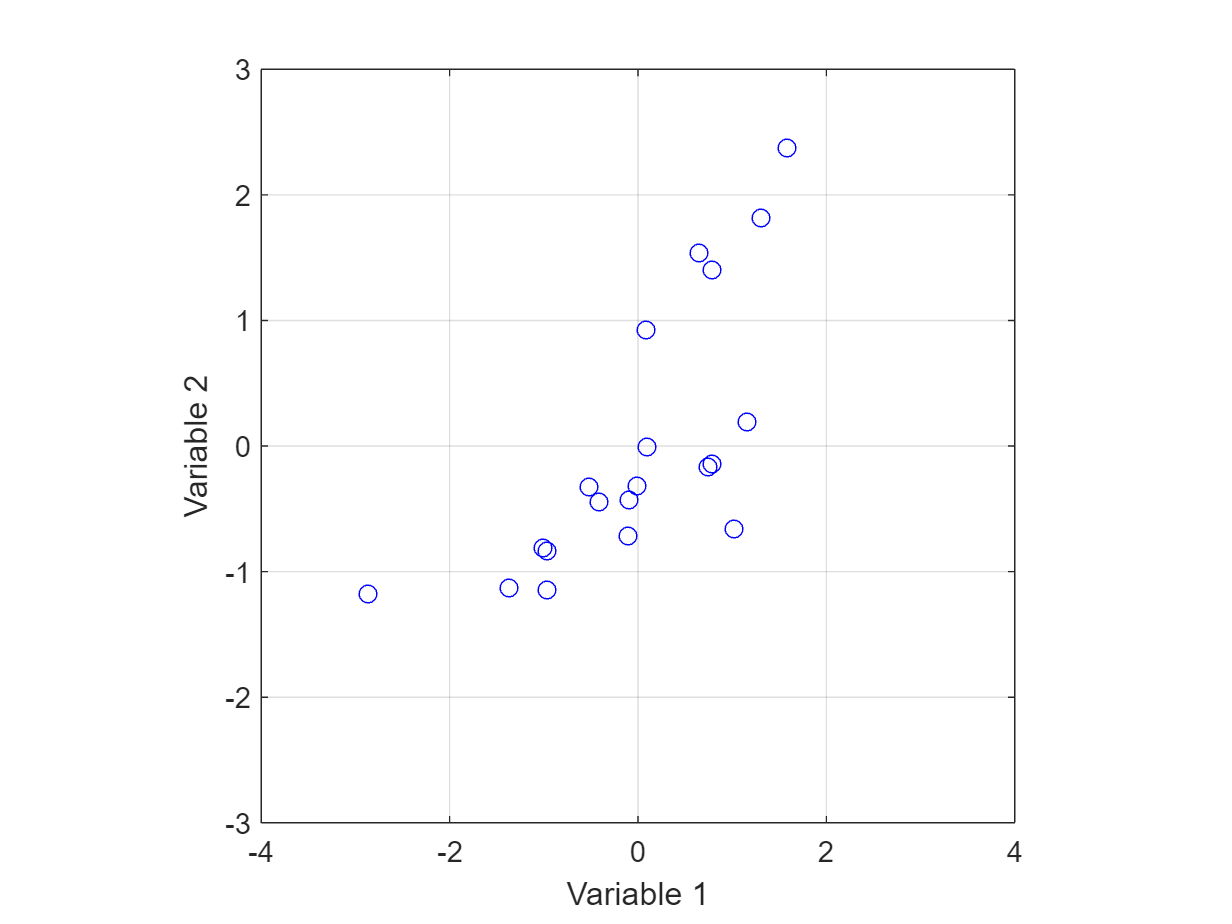

figure(2)
clf
scatter(centered1,centered2,'bo')
xlabel ('Variable 1')
ylabel ('Variable 2')
ylim([-3 3])
xlim([-4 4])
pbaspect([1 1 1])
grid on
box on

The `pca` function in Matlab centers the data by default, but it is important to understand why this step is conducted. If your variables are on the same scale of measurement, then centering your data is the only preprocessing necessary before you apply PCA. However, if they are not on the same scale that data *also *needs to be scaled so that everything is on the same scale. These steps can be done in sequence, or at once by computing the zscore for each data point ($z_i \;=\left(\frac{x_i -\bar{x} }{\sigma_x }\right)$). If you have to scale your data, do it before plugging it into the pca function and set the 'centered' argument to 'false'. (`pca(zData,'centered',false)`).  

### Step 2: Find the Principal Components

#### Finding Principal Component (PC1)

The first principal component is a vector that points towards the direction(s) of maximum variation in your data. In a figure you can eyeball this direction by looking at the data point cloud and guess which direction has the largest spread.

There are a few procedures for finding these principal components. The two most common are Eigenvalue Decomposition  and Singular Value Decomposition (SVD). Both are beyond the scope of this course, but if you are interested see: [Gilbert Strang's Lecture on SVD](https://www.youtube.com/watch?v=rYz83XPxiZo).  In Matlab, the `pca` function defaults to using SVD. In brief, finding the principal components using SVD amounts to:

- Plotting a line that runs through the origin (0,0)

- Projecting each data point onto the line

- Calculating the distance between the projected points and the origin

- Squaring these distances (to avoid negative numbers)

- Summing the squared distances.

- Rotate the line and repeat Steps 2-5 until you have found the vector that maximizes the summed squared-distances. 

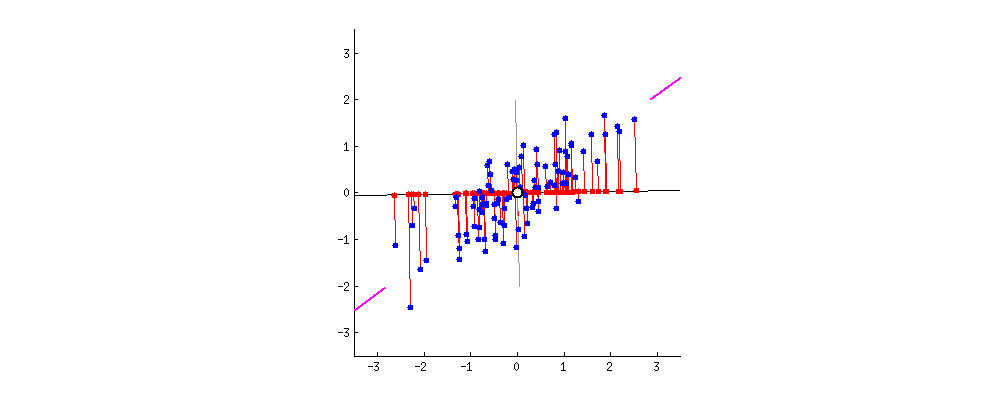

[Source](https://builtin.com/data-science/step-step-explanation-principal-component-analysis)

The direction (i.e. vector) that maximizes the sum of squared distances is called *Principal Component 1 (PC1) *. The nomenclature tends to get a bit confusing. The word principal component is sometimes used for the vector, and sometimes for the projection of the data point onto that vector (which is, technically, the correct usage as the projection is the component). These vectors are also called eigenvectors. Matlab calls the vectors 'coefficients' and the projections 'loading scores'; they are the first and second output argument of the pca function.

#### Finding PCs 2+

The total number of potential PCs is determined by the number of variables in your data. For instance, in our toy example, there are 2 variables and therefore 2 principal components. The specific component numbers (e.g., PC1, PC2, PC3, etc.) correspond, in decreasing order, to the amount of variance explained by that PC. In other words, PC1 explains the most variance, PC2 the second most, etc.  Importantly, these vectors are not correlated to each other (i.e., they are orthogonal). 

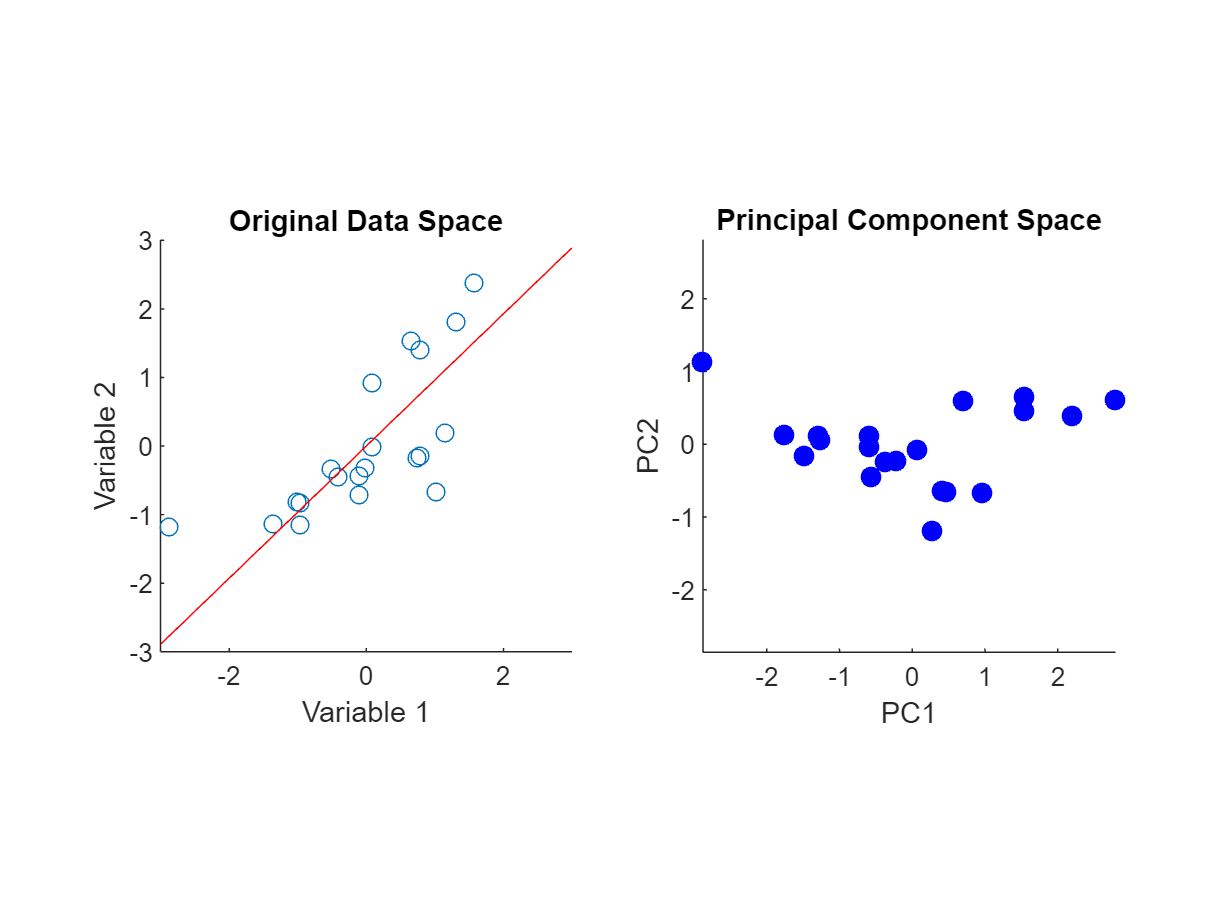

% let's run PCA and plot projected points onto the two PCs
[eigVect,loadingScores, eigenValues] = pca([centered1,centered2],'Centered',false);
figure(4)
clf


subplot(1,2,1)
% plot the orginal (centered) data and add the first principal component
scatter(centered1,centered2,'o'); hold on
xPred = -3:0.5:3;
pc1 = (eigVect(2,1)/eigVect(1,1)).*xPred;% the division with the eigenvectors are used to compute the slope of the line
plot(xPred,pc1,'r')
axis equal
xlabel 'Variable 1'
ylabel 'Variable 2'
title 'Original Data Space'
pbaspect([1 1 1])

subplot(1,2,2)
scatter(loadingScores(:,1),loadingScores(:,2),50,'b',"filled")
xlabel 'PC1'
ylabel 'PC2'
title 'Principal Component Space'
axis equal
pbaspect([1 1 1])

The left panel shows the original data representation and the red line identifies the direction in that 2D space along which the variance is maximal (i.e. it is the direction associated with the first principal component, or PC1, for short). The right panel shows exactly the same data on two new axes. The horizontal axis represents PC1 (direction of largest variance) and vertical is PC2 (next largest variance). The scales on the axes are the same and that allows you to see immediately that there is a lot of variation horizontally, and very little vertically. The change of data representation going from left to the right panel is lossless; you can descibe each data point as some combination of Variabel 1 and Variable 2, or as the combination of PC1 and PC2.  However, the representation in the right panel makes it clear that knowing PC1 is more informative than knowing PC2. So , if you had to chose a single PC to represent a datapoint you would pick PC1; that PC explains most of the variance in the data set. In the next section, we will quantify the amount of variance explained by each of the components. 

### Step 3: Calculate the Variation Accounted for by Each PC

The amout of variation for each component is determined by the third output of the pca function. Matlab calls this 'latent'  (no idea why); technically these are the eigenvalues corresponding to each principal component vector. The eigenvalues for a given PC is simply the sum of the squared distances for each data point projected onto the PC to the origin (see step 5 in the 'Finding Principal Component' section) You will only ever need them to calculate the explained variance and that is computed simply by dividing each eigenvalue by the sum of all eigenvalues;

varExplained = eigenValues./sum(eigenValues)

varExplained =     0.8635
    0.1365


This supports what we saw in the previous figure. Namely that PC1 accounts for a lot (86%) of the variance in the data, while PC2 accounts for the remaining 14%.

## Spike Sorting Using PCA

One example of how PCA is used in neuroscience is spike sorting, organizing spikes into groups based on the putative neuron it came from. This can be done using methods such as the size of the peak,trough, or another feature. However, these features are all ad-hoc (although they could be based on biophysics in this case). Using PCA allows the data decide which  features are "interesting".

#### The Data

The data for this demonstration can be found in the file called `spikeWaveForms.mat`. The file contains two variables:

- `samples` is a vector containing the sampling points referenced to the time point at which a spike was detected (e.g., detection time = 0). 

- `spikes` contains [samples x number of waveforms] matrix with the voltage for each waveform at each sampling point. 

So, in this data set we have 40 (samples) features per waveform in the original space, based on those 40 features we would like separate certain shapes (waveforms), but comparing 40 numbers across 3328 waveforms is too complex. Instead, we ask whether we can reduce the complexity of the description to something lower dimensional using PCA.

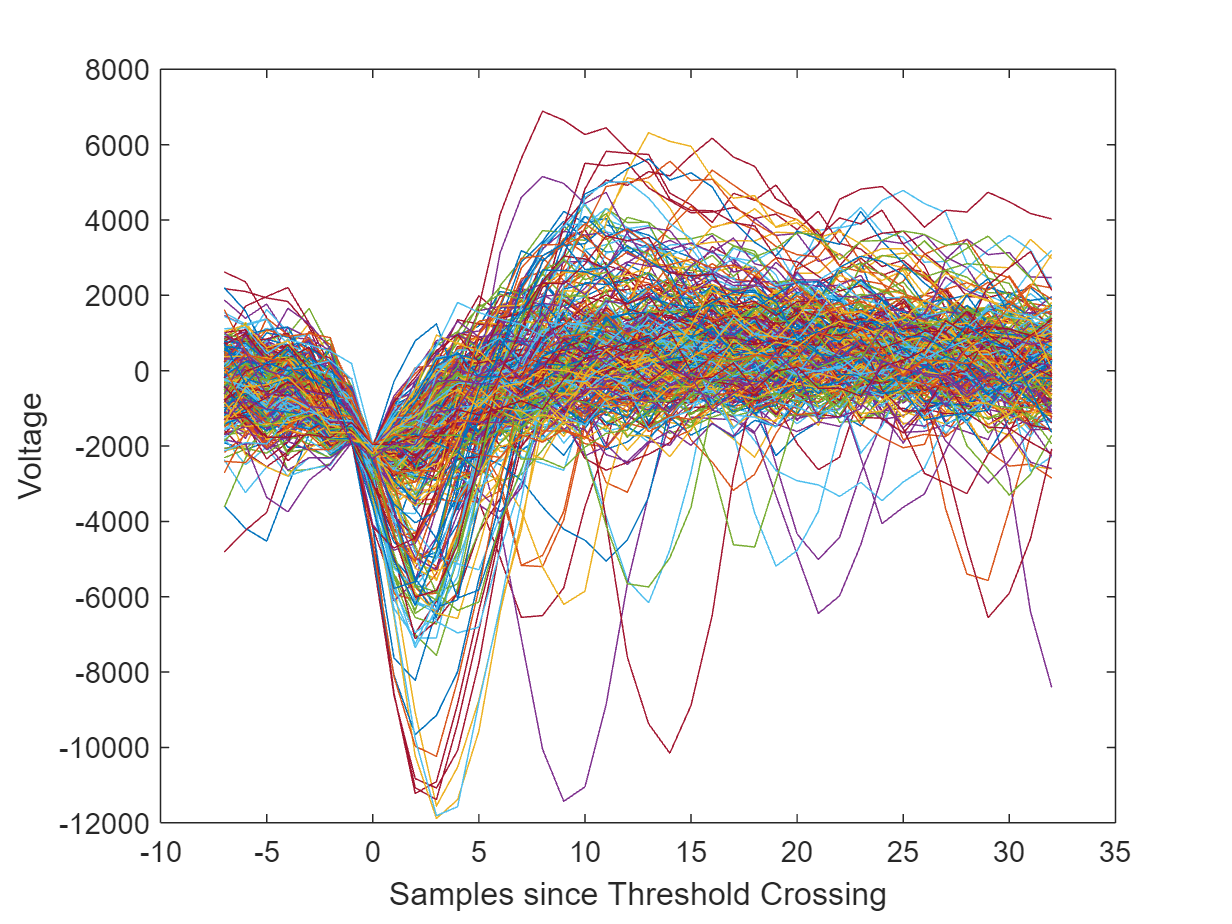

load ../data/spikeWaveForms     
figure(6);
clf
% visualize the data
plot(samples,spikes(:,1:10:end));% Plotting only every 10th waveform to save time.
xlabel 'Samples since Threshold Crossing'
ylabel 'Voltage'

In this representation, each waveform is represented by 40 numbers. Another way of thinking about these data is that each waveform is a point in a 40-dimensional space. You may already see that there are some waveforms with a very deep  trough, one set with intermediate troughs, and then some very shallow ones. Maybe these correspond to spikes from  distinct neurons, but this is hard to see in this representation. Reducing the dimensionality using PCA may provide some clarity.

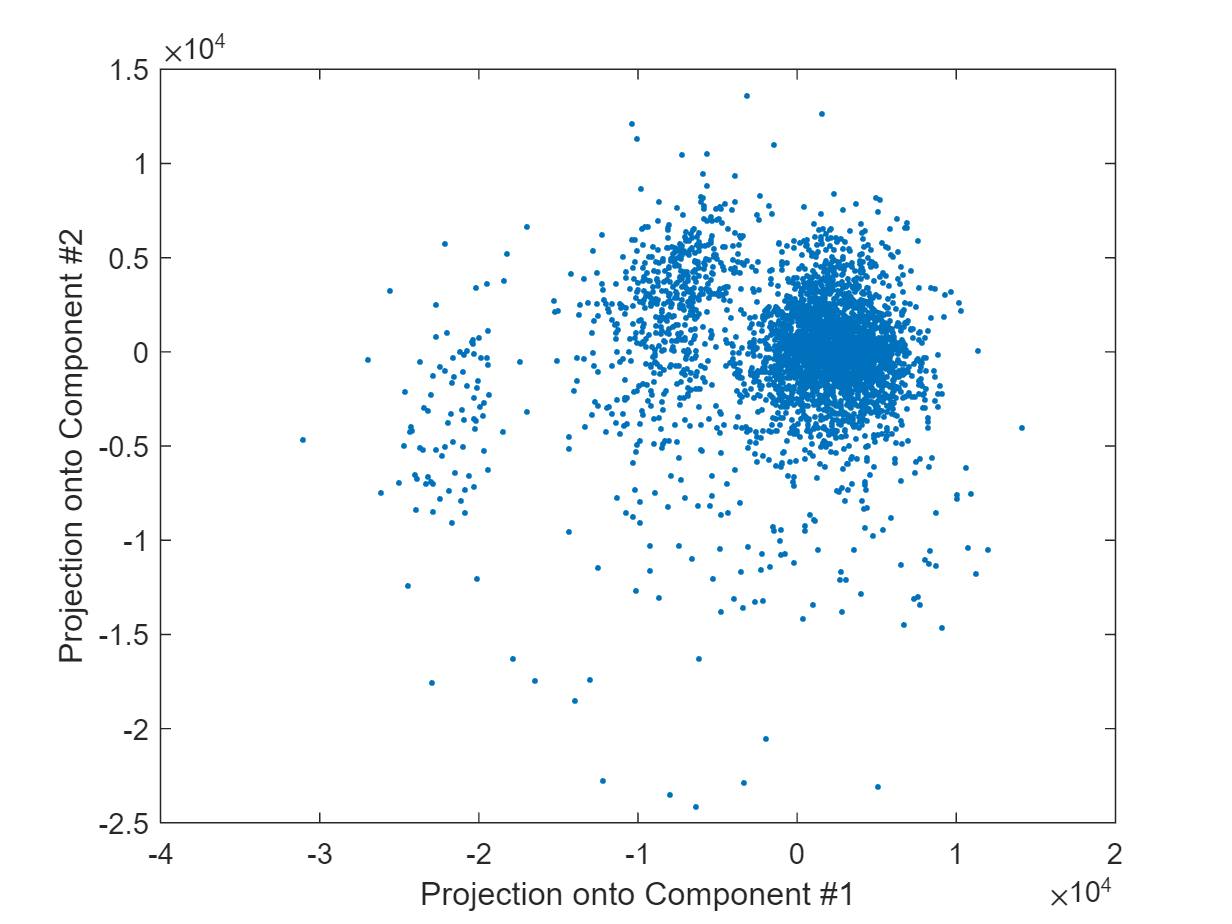

% compute PCA
[components,projections,eigenValues] = pca(spikes');

% Show each spike as a projection on the first two PCs
clf
plot(projections(:,1),projections(:,2),'.')
xlabel 'Projection onto Component #1'
ylabel 'Projection onto Component #2'

Now we use only two numbers (PC1 and PC2) to represent the same data. Obvously this is not lossless (i.e. we cannot take just these numbers and reproduce the full waveforms), but this represenations shows that there are three clusters (which may correspond to three waveforms, and therefore putatively three neurons).

While we could select the data belong to each cluster manually using ginput, since we know the number of clusters,  K-Means clustering is a simple but effective techinique. We will not go into kmeans clustering in this document, but if you would like to learn more about it, here is a nice video: [Explanation of K-means Clustering](https://www.youtube.com/watch?v=4b5d3muPQmA&feature=youtu.be).

nrClusters= 3;
color = 'rgb';
dimensions = 1:2;
[unit,c] =kmeans(projections(:,dimensions),nrClusters,'Replicates',10);


Using this classification by kmeans, we plot the projections onto the components using colors to identify each unit, as well as the average waveform of each unit.

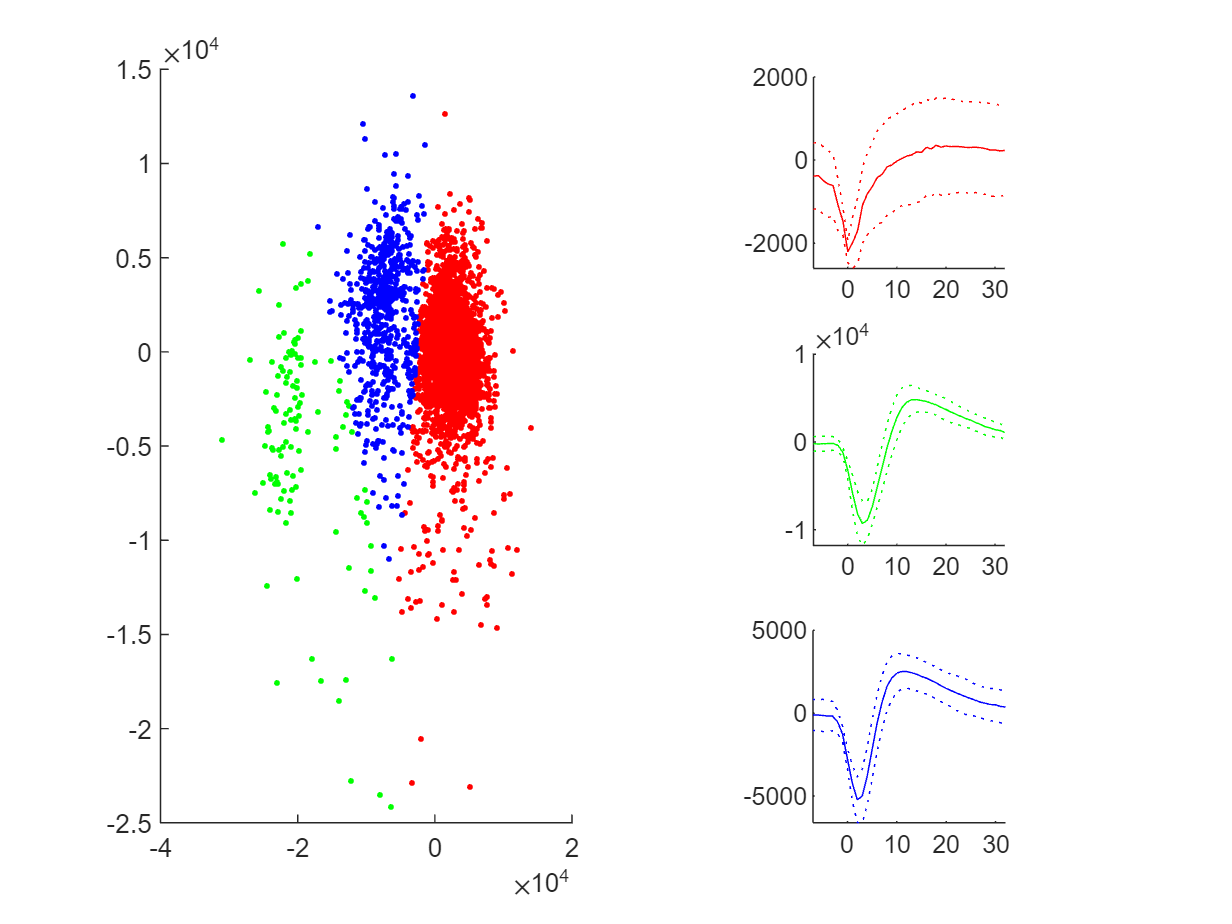

clf;
xlabel 'Sample'
ylabel 'Average Waveform'
for i=1:3
    IN = unit==i;
    subplot(3,2,[1 3 5]); 
    hold on
    plot(projections(IN,1),projections(IN,2),[color(i) '.']);
     
    m   = mean(spikes(:,IN),2);
    sd = std(spikes(:,IN),1,2);
    
    subplot(3,2,(i-1)*2+2);
    hold on
    plot(samples,m,color(i));
    plot(samples,m+sd,[color(i) ':']);
    plot(samples,m-sd,[color(i) ':']);
    pbaspect([1 1 1])
end

You can see that kmeans is not perfect (probably a manual sorter would have assigned some blue data points in the left panel to the red cluster), but it does a pretty good job classifying the clusters in this 2-dimensional PCA space. This illustrates how the lower dimensional representation (some information is lost) is nevertheless more useful for the purpose of classification. 

The panels on the right show the average waveforms for each of the clusters. Blue and red look like reasonably well isolated units, but green is probably a mixture of spikes from many neurons ("multi-unit or hash").

Let's look under the hood a little bit to understand better what PCA does. First, let's visualize the first three principal components

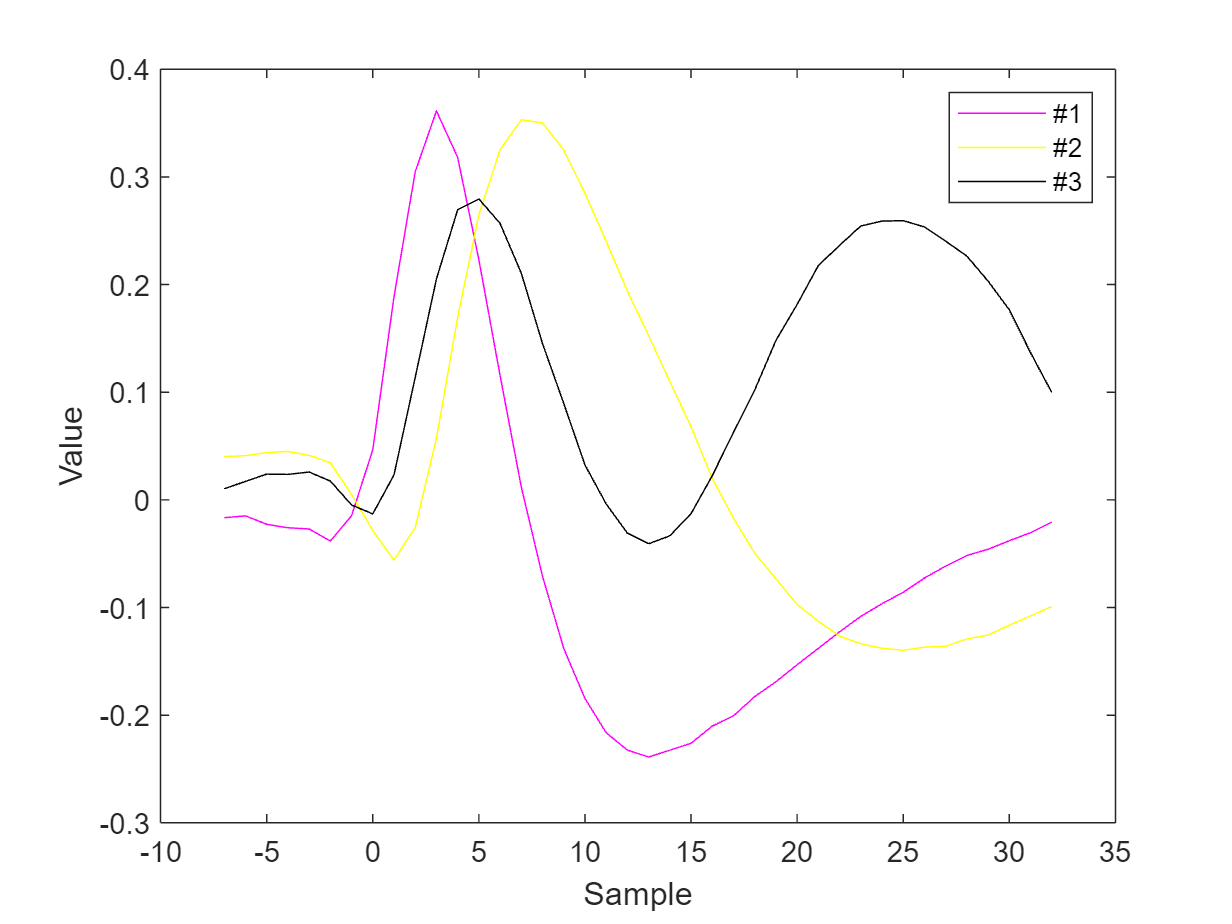


% Show the first three principal components
clf; 
plot(samples,components(:,1),'m');
hold on ;
plot(samples,components(:,2),'y')
plot(samples,components(:,3),'k')
xlabel 'Sample'
ylabel 'Value'
legend('#1','#2','#3');

This figure shows the "directions" in the high-dimensional original space (40 samples = 40 dimensional) that explain most variance. Put differently if you wanted to use just 1 number to describe a waveform, then you should use the projection of the waveform onto the magenta curve. (A projection quantifies how much an individual waveform looks like the magenta curve). PCA found this magenta curve and by construction you know that this is the curve that describes the largest fraction of the variance in the dataset. 

The most important caveat about principal components is that they do not necessarily refer to physical entities. In other words, while it is tempting to interpret the magenta curve as a spike waveform of a unit, this would be incorrect. It is an abstract shape (a direction in the 40 dimensional space), some waveforms look a lot like this, others do not. Maybe it is easier to phrase this with reference to PC3 (black); the fact that this is a principal component does not mean that action potentials show this strange wiggle, only that a linear combination of this wiggle together with the #1 and #2 shapes describes all waveforms quite well. 

How well? That's is given by the explained variance:

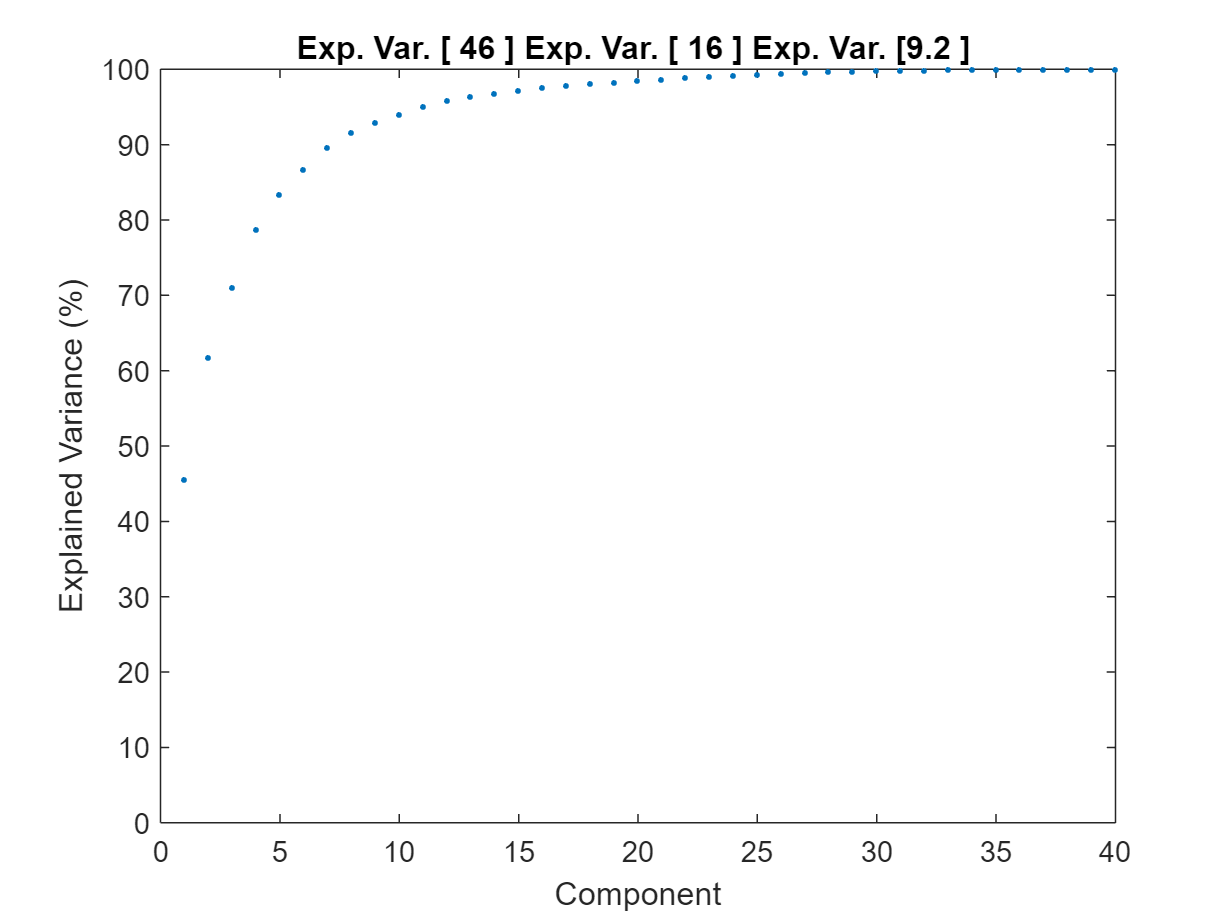


%Show the cumulative explained variance for each component.
explainedVariance = 100*eigenValues./sum(eigenValues);
clf;
plot(cumsum(explainedVariance),'.');
set(gca,'YLim',[0 100])
xlabel 'Component'
ylabel 'Explained Variance (%)'
title(sprintf('Exp. Var. [%3.2g ] ',explainedVariance(1:3)))

This figure shows that the amount of variance explained does not increase linearly. Instead, the increases in the amount of explained variances become smaller and smaller. In this dataset, PC1(magenta curve) accounts for 46% of the variance, and PC#2 (yellow curve)  adds another 16%. That means that the 2D represenation we used to the clustering accounts for over 60% of the variance in the complete data set . Put differently PCA reduced the complexity from a 40 dimensional space to a 2 dimensional space and yet only lost 40% of the variance. The high fraction of explained variance gives us confidence that it is reasonable to project the data down to the first two components (although a case courl be made that PC#3 with 9% explained variance should be included too). In either case,theprojecton to 2 or3 dimensions makes it much easier to visualize and to analyze (e.g. with a clustering algorithm,which tend to get lost in high dimensional spaces).

## References and Additional Resources

[StatQuest PCA Step-by-Step](https://www.youtube.com/watch?v=FgakZw6K1QQ&feature=youtu.be)

[ISLR Unsupervised Learning Playlist](https://www.youtube.com/playlist?list=PLAOUn-KLSAVMOah3Vz100xM0eTLdj5ovq)

[ISLR PDF--See Chapter 10](http://faculty.marshall.usc.edu/gareth-james/ISL/ISLR%20Seventh%20Printing.pdf)